# **Projeto Eletromag**

**Equipe **

- Guilherme Augusto Chaves de Carvalho

- Daniel Costa Delattre

- Rafael Seicali Malcervelli

**1. Modelando a antena **

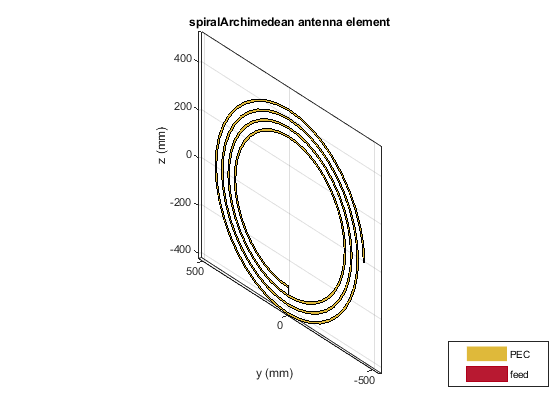

antE = spiralArchimedean('NumArms',1,'Turns',4, 'InnerRadius',30e-2, 'OuterRadius',45e-2,"Tilt",90,"TiltAxis","Y");
show(antE)

**2. Calculando a impedância de sua antena**

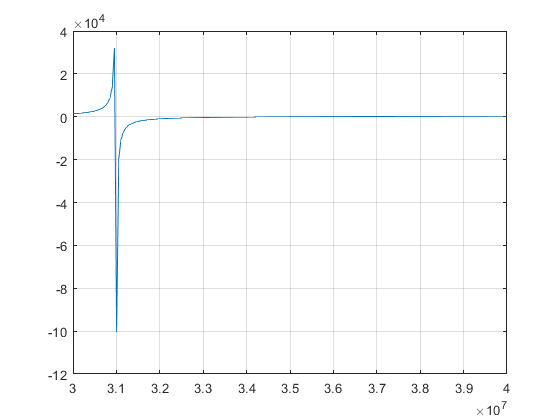

freq = linspace(3e7,4e7,200);
impedancia = impedance(antE,freq);
img_antena = imag(impedancia);
plot(freq,img_antena)
%ylim([-100, 100])
grid

% frequencia de ressonancia = 3.52e7 para img zero e wc = = 3.09 e7

**3. Antena receptora**

antR = spiralArchimedean('NumArms',1,'Turns',4, 'InnerRadius',30e-2, 'OuterRadius',45e-2,'Tilt',90,"TiltAxis","Y");
show(antR)

Array de antenas

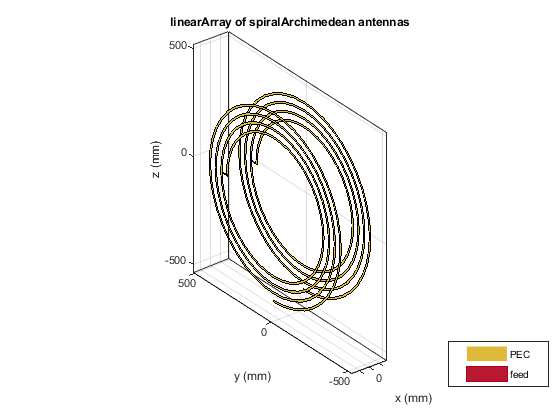

la = linearArray('Element',[antE,antR],'Tilt',90);
la.ElementSpacing = 15e-2;
show(la)

**4. Simulando o acoplamento**

ganhos = sparameters(la, freq);

**5. Visualizando os ganhos **

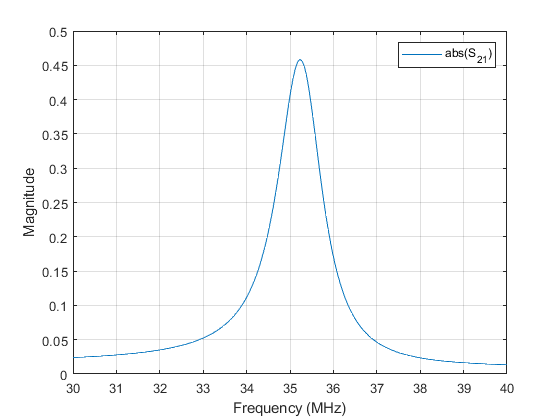

rfplot(ganhos,2,1,'abs')

ganhos_db = abs(rfparam(ganhos,2,1));

É importante pois é a frequência de ressonancia. No grafico a maior magnitude é a que tem frequencia parecido com a de ressonancia 

**6. Visualização 3D** 

distancias = linspace(5e-2, 50e-2,30);
len_dist = length(distancias)

len_dist = 30

len_freq = length(freq)

len_freq = 200

M_ganhos = [];


for i = 1:length(distancias)
    la.ElementSpacing = distancias(i);
    ganhos_3d = sparameters(la, freq);
    lista_ganhos = rot90(abs(rfparam(ganhos_3d,2,1)));
    M_ganhos = [M_ganhos;lista_ganhos];
end

M_ganhos

M_ganhos =     0.1040    0.1045    0.1049    0.1053    0.1058    0.1063    0.1068    0.1073    0.1079    0.1084    0.1090    0.1096    0.1102    0.1108    0.1114    0.1121    0.1128    0.1135    0.1142    0.1150    0.1158    0.1166    0.1175    0.1183    0.1192    0.1202    0.1212    0.1222    0.1232    0.1243    0.1254    0.1266    0.1278    0.1291    0.1304    0.1318    0.1332    0.1346    0.1362    0.1378    0.1395    0.1412    0.1430    0.1449    0.1469    0.1489    0.1511    0.1534    0.1557    0.1582
    0.0812    0.0816    0.0820    0.0824    0.0828    0.0832    0.0837    0.0841    0.0846    0.0851    0.0856    0.0861    0.0867    0.0872    0.0878    0.0884    0.0890    0.0897    0.0903    0.0910    0.0917    0.0924    0.0931    0.0939    0.0947    0.0955    0.0964    0.0973    0.0982    0.0992    0.1001    0.1012    0.1022    0.1033    0.1045    0.1057    0.1069    0.1082    0.1095    0.1109    0.1124    0.1139    0.1155    0.1171    0.1188    0.1206    0.1225    0.1245    0.12

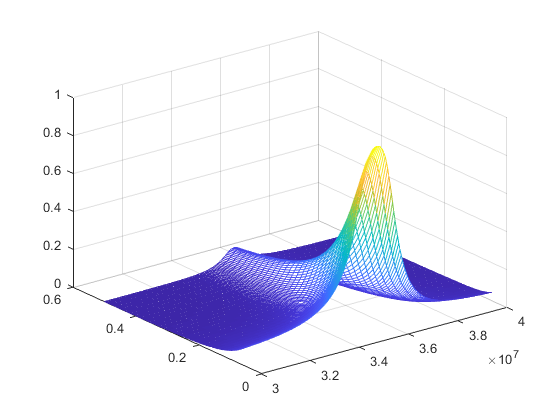

% Plotando o grafico 3d
mesh(freq, distancias, M_ganhos)

**7. Impedancia do modelo para diferentes frequencias**

sigma = 42;
wc = 3.09e7

wc = 30900000

L = sigma/wc

L = 1.3592e-06

C = 1/(sigma*wc)

C = 7.7053e-10

length(freq)

ans = 200


lista_impedancias = zeros(1,length(freq));

for i = 1:1:length(freq)
    w = freq(i);
    XL = 1i*w*L;
    XC = 1/(1i*w*C);
    impedancia_modelo = (XL*XC)/(XL+XC) + 4*XL;
    lista_impedancias(1,i) = impedancia_modelo;
end
length(lista_impedancias)

ans = 200

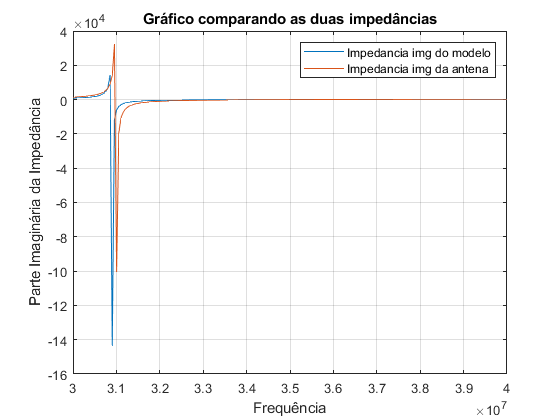

img_modelo = imag(lista_impedancias);
plot(freq,img_modelo,freq,img_antena)
t = title('Gráfico comparando as duas impedâncias');
grid
legend('Impedancia img do modelo','Impedancia img da antena')
xlabel('Frequência') 
ylabel('Parte Imaginária da Impedância') 

**8. Ganho em Função mutua**

Uf = 1

Uf = 1


lista_M = linspace(0, 1/wc, 30)

lista_M = 	1.0e+-7 *

         0    0.0112    0.0223    0.0335    0.0446    0.0558    0.0670    0.0781    0.0893    0.1004    0.1116    0.1228    0.1339    0.1451    0.1562    0.1674    0.1786    0.1897    0.2009    0.2120    0.2232    0.2343    0.2455    0.2567    0.2678    0.2790    0.2901    0.3013    0.3125    0.3236


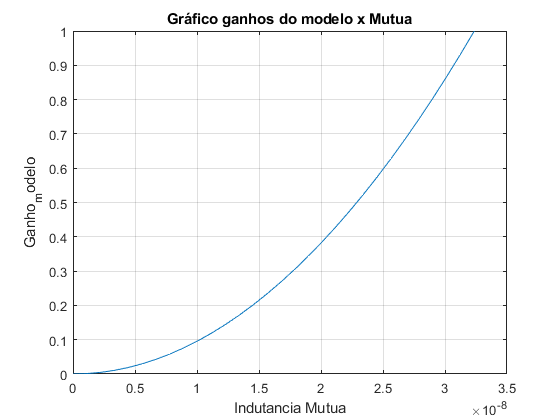

lista_ganhos = zeros(1,length(lista_M));
for n = 1:1:length(lista_M)
    Xm  = 1i*wc*lista_M(n);
    Z = [1 -Xm;
         Xm -1];
    V = [Uf;0];
    I = rot90(linsolve(Z,V));
    lista_ganhos(1,n) = abs((I(2)/I(1))^2);
end


plot(lista_M,lista_ganhos)
grid
t = title('Gráfico ganhos do modelo x Mutua');
xlabel('Indutancia Mutua') 
ylabel('Ganho_modelo') 

**9. Funcao mutua pela distancia**

wr = 3.52e7

wr = 35200000

lista_ganhos2 = zeros(1,length(lista_M));
for i = 1:length(distancias)
    la.ElementSpacing = distancias(i);
    ganhos_3d = sparameters(la, wr);
    lista_ganhos2(1,i) = rot90(abs(rfparam(ganhos_3d,2,1)));
end

lista_ganhos2

lista_ganhos2 =     0.9670    0.9073    0.8183    0.7247    0.6348    0.5543    0.4848    0.4259    0.3766    0.3354    0.3009    0.2719    0.2475    0.2267    0.2091    0.1938    0.1807    0.1692    0.1592    0.1503    0.1424    0.1353    0.1290    0.1233    0.1180    0.1132    0.1088    0.1048    0.1010    0.0975


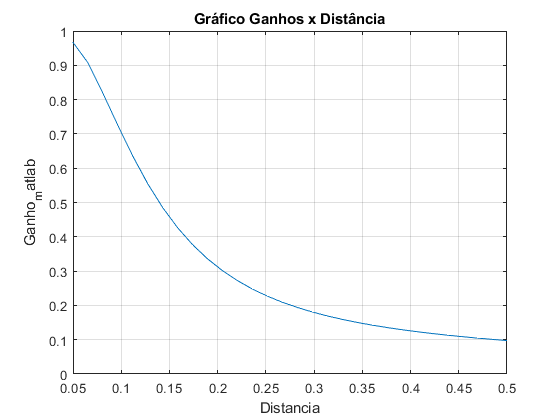

plot(distancias,lista_ganhos2)
grid
t = title('Gráfico Ganhos x Distância');
xlabel('Distancia') 
ylabel('Ganho_matlab') 

%xlswrite('dadosGanhos.xls',lista_ganhos2)
%xlswrite('dados_modelo.xls',lista_ganhos)

**10. Equacionando**

Utilizando o excel consguimos encontrar as equações das curvas de tendencia dos gráficos:

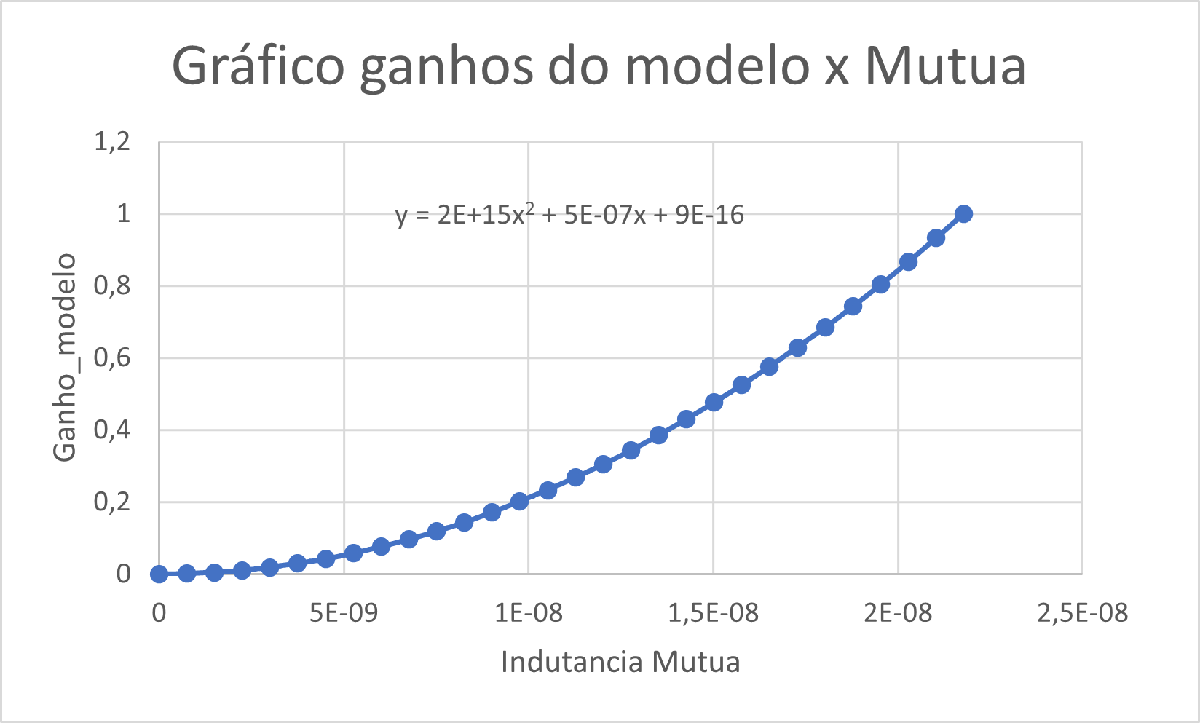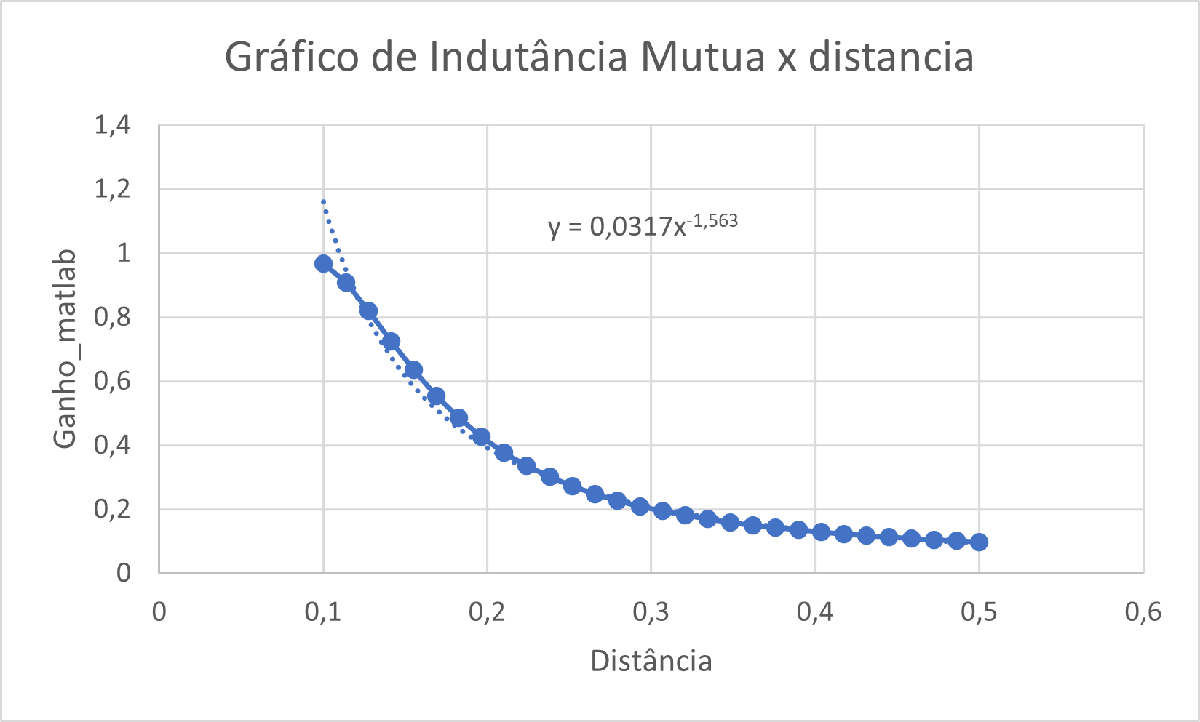

Igualando os Y's dos gráficos para encontrarmos uma equação de M em função de d:

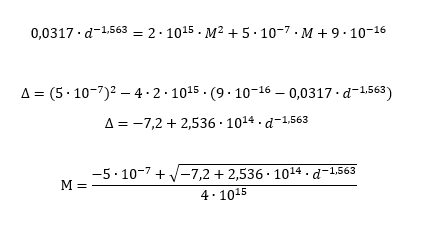

**11. Plotando Gráfico de M x d **


Lista_mutua = zeros(1,length(distancias));
for i = 1:length(distancias)
    delta = -7.2 + 2.536e14*(distancias(i)^-1.563);
    m = (-5e-7 + sqrt(delta))/(4e15);
    Lista_mutua(1,i) = m;
end

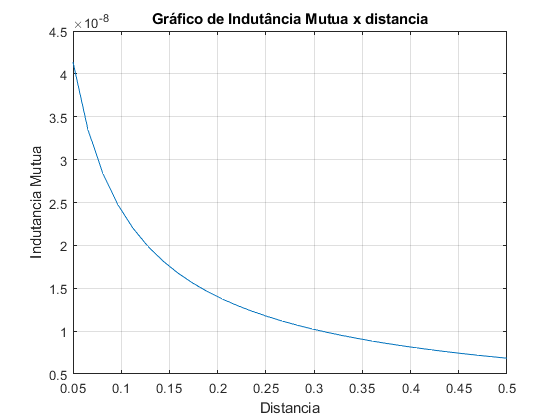

plot(distancias,Lista_mutua)
grid 
t = title('Gráfico de Indutância Mutua x distancia');
xlabel('Distancia') 
ylabel('Indutancia Mutua') 